Using polifit

x=[1:0.5:10]

x =     1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000


sz=size(x)

sz =      1    19


rnd=randn(sz)   %generate pseudo-rnd numbers (0-1) normally distributed

rnd =    -0.1454   -0.3862    1.3162   -0.7965    0.1354    0.4178    0.8199   -0.8544    0.3573    2.7485   -1.5130    0.4340   -0.2298   -0.8271   -0.8320    0.4979    2.3156   -0.7938    0.5410


y=x.^2 + rnd*7   %quadratic func + rnd to alter data  

y =    -0.0176   -0.4537   13.2134    0.6748    9.9481   15.1746   21.7392   14.2695   27.5012   49.4893   25.4092   45.2879   47.3916   50.4604   58.1761   75.7353   97.2094   84.6932  103.7867



plot (x,y,'o')   
hold on

Now use polifit function to get a polynomial. Look documentation polyfit and polyval how to get 95% CI

Then compare with polyval



n=7

n = 7

p= polyfit(x,y,n)     %returns coef of polynomial descending degrees of n

p =     0.0017   -0.0727    1.2730  -11.4237   55.9633 -146.3750  190.5196  -91.3045


                        % last coef intersects y (ie, no x)
l=length(x)

l = 19

yy_fit=zeros(1,l);    %creates a matrix zeros dim 1, length x
for i =1:l
    %yy_fit(i) = 0
    for j=0:n
        yy_fit(i)=yy_fit(i) + p(n-j+1)   *x(i)^j  ;
    end
    
end

plot (x,yy_fit, 'b-')

yy_polyval=polyval (p,x);

yy_polyval =    -1.4183    5.0421    5.4577    5.9192    8.5379   13.2143   18.9160   24.5292   29.3508   33.2846   36.8083   40.7761   46.1227   53.5333   63.1455   74.3490   85.7463   95.3431  101.0308


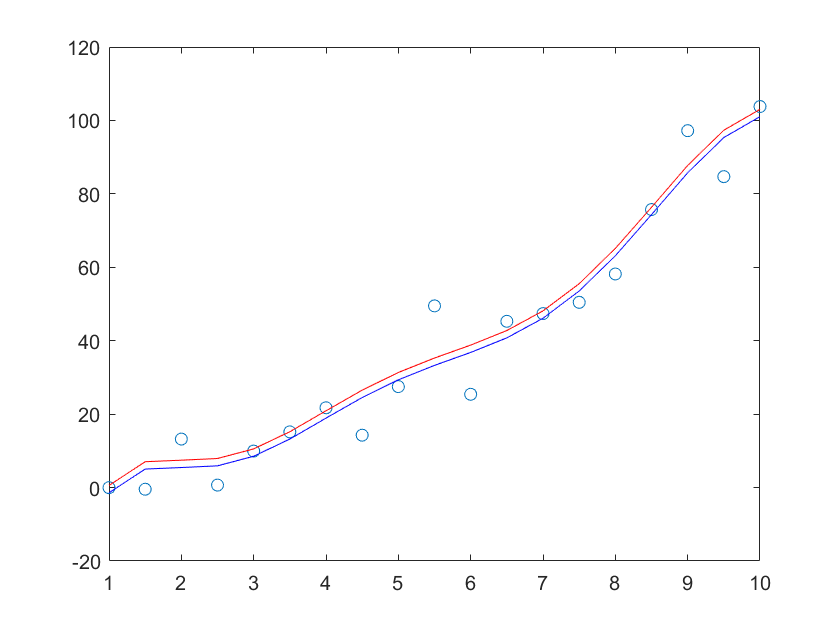

plot (x, yy_polyval+2, 'r-')     %y values with polyval. +2 for visualization

legend('Random data', 'My polynomial', 'Polyval')
hold off